## **Heavy Frame**

 AERO60002 Aerospace Vehicle Design 2024-2025

**Project G1**

% Housekeeping
clear
clc
close all

### **0 Design Parameters**

**0.1 Sea Level**

[T0, a0, P0, rho0] = atmosisa(0);  % Sea level condition
g = 9.80665;                       % Standard acceleration of gravity (m/s^2)

**0.2 Fuselage Properties**

D = 6.38;                          % Fuselage diameter (m)
r = D ./ 2;                        % Fuselage radius (m)
C = 2 * pi * r;                    % Fuselage circumference (m)

**0.3 Material Properties**

E_f = 67000000000;                 % Young's Modulus (N/m^2)
rho_f = 2860;                      % Density (kg/m^3)
sigma_y = 614000000;               % Tensile yield stress (Pa)
tau_y = sigma_y ./ sqrt(3);        % Shear yield stress (Pa)

pi * sqrt(E_f/sigma_y)

ans = 32.8173

**0.4 Critical Loading Conditions**

Q = 1.142825564111328e+05;        % Maximum shear force (N)
P = 0;                            % Maximum tangential load (N)
T = 0;                            % Maximum torque (Nm)

### **1 WISE curve**

**1.1 Find WISE curve**

% Define theta range (0 to 2*pi for full fuselage section)
theta = linspace(0, 2 * pi, 1000);

% Compute shear flow distributions for P, Q, and T load cases
M_P = -(P * r / (2 * pi)) .* ((3 * sin(theta) / 2) + (pi - theta) .* (cos(theta) - 1));
N_P = -(P / (2 * pi)) .* ((sin(theta) / 2) - (pi - theta) .* cos(theta));
S_P = -(P / (2 * pi)) .* (((pi - theta) .* sin(theta)) - 1 - (cos(theta) / 2));

M_Q = -(Q * r / (2 * pi)) .* ((cos(theta) / 2) - (pi - theta) .* sin(theta) + 1);
N_Q = -(Q / (2 * pi)) .* ((3 * cos(theta) / 2) + (pi - theta) .* sin(theta));
S_Q = -(Q / (2 * pi)) .* (((pi - theta) .* cos(theta)) - (sin(theta) / 2));

M_T = -(T / (2 * pi)) .* (pi - 2 * sin(theta) - theta);
N_T = -(T / (2 * pi * r)) .* ((3 * cos(theta) / 2) + (pi - theta) .* sin(theta));
S_T = -(T / (2 * pi * r)) .* (1 + 2 * cos(theta));

% Compute total shear flow distributions
M_total = M_P + M_Q + M_T;
N_total = N_P + N_Q + N_T;
S_total = S_P + S_Q + S_T;

1.2 Plotting the result

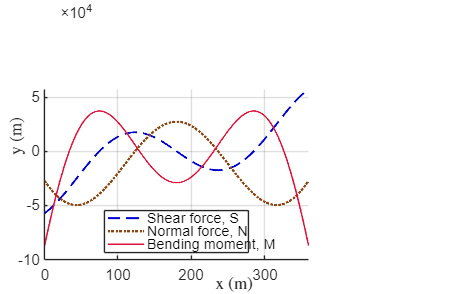

figure(1)

clf;

hold on;

plot(theta * 180 / pi, S_total, '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25);
plot(theta * 180 / pi, N_total, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.5);
plot(theta * 180 / pi, M_total, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.);

% Legends
legend("Shear force, S", "Normal force, N", "Bending moment, M", "Location", "best", 'NumColumns', 1, FontSize = 9)

% Axis labels with LaTeX font
xlabel('x (m)', 'Interpreter', 'latex');
ylabel('y (m)', 'Interpreter', 'latex');

% Set plot limits and grid
xlim([0 360]);
grid on;

hold off;

% Set figure size
set(gcf, 'Position', [0 0 500 325]);

1.3 Find the maximum

S_max = max(abs(S_total))

S_max = 5.7141e+04

N_max = max(abs(N_total))

N_max = 4.9618e+04

M_max = max(abs(M_total))

M_max = 8.7033e+04

### **2 Optimisation Problem using fmincon with Global research**

compare [fmincon](https://www.mathworks.com/help/optim/ug/fmincon.html) with [GlobalSearch](https://ww2.mathworks.cn/help/gads/globalsearch.html) and [ga](https://ww2.mathworks.cn/help/gads/ga.html), using the best result

**2.0 Initial conditions**

Define the objective function for optimisation problem

fun = @(x) mass_hf(x(1), x(2), x(3), x(4));            % (t_web, t_fl, b_f, h_f)

Define initial point for the objective function

x0 = [10 / 1000, 10 / 1000, 200 / 1000, 300 / 1000];   % take average from literiture review

Boundary conditions

lb = [1 / 1000, 1 / 1000, 10 / 1000, 10 / 1000];       % change dynamically
ub = [0.05, 0.05, 0.5, 0.5];                           % change dynamically

Nonlinear constraints

nonlcon = @Non_linear_hf_3;

**2.1 Define problem**

Create optimization problem [createOptimProblem](https://ww2.mathworks.cn/help/gads/createoptimproblem.html)

problem = createOptimProblem('fmincon', 'objective', fun, 'x0', x0, 'lb', lb, 'ub', ub, 'nonlcon', nonlcon, 'options', optimoptions('fmincon', 'Display', 'iter'));

[GlobalSearch](https://ww2.mathworks.cn/help/gads/globalsearch.html)

gs = GlobalSearch('NumTrialPoints', 2000, 'MaxWaitCycle', 100);

**2.2 Run optimisation**

[x_opt, f_opt] = fmincon(fun, x0, [], [], [], [], lb, ub, nonlcon)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x_opt =     0.0091    0.0124    0.0931    0.1073


f_opt = 188.0029

[x_opt, f_opt] = run(gs, problem);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    4.012681e+02    4.980e+08    8.375e+02
    1      10    3.575349e+02    4.747e+08    8.627e+03    2.256e-02
    2      15    3.546188e+02    4.733e+08    9.124e+03    2.214e-03
    3      20    2.639289e+02    3.738e+08    2.842e+04    9.001e-02
    4      25    2.624077e+02    3.714e+08    2.869e+04    1.542e-03
    5      30    2.539916e+02    3.575e+08    3.014e+04    8.492e-03
    6      35    2.537787e+02    3.572e+08    3.018e+04    2.073e-04
    7      40    2.521872e+02    3.560e+08    3.052e+04    1.164e-03
    8      45    2.424790e+02    3.492e+08    3.266e+04    7.808e-03
    9      50    2.424237e+02    3.491e+08    3.268e+04    2.268e-05
   10      55    2.243476e+02    3.109e+08    4.046e+04    2.432e-02
   11      60    1.513765e+02    1.797e+08    1.432e+05    1.358e-01
   12      65    1.706422e+02    7.899e+07    1

  104     583    1.880106e+02    4.909e-01    1.767e+03    1.953e-08


  105     589    1.880106e+02    4.909e-01    1.767e+03    1.949e-08


  106     595    1.880105e+02    4.909e-01    1.767e+03    1.966e-08


  107     600    1.880103e+02    4.909e-01    1.767e+03    3.997e-08


  108     606    1.880103e+02    4.909e-01    1.767e+03    2.052e-08


  109     612    1.880102e+02    4.909e-01    1.767e+03    2.091e-08


  110     618    1.880101e+02    4.909e-01    1.767e+03    2.081e-08


  111     623    1.880099e+02    4.909e-01    1.767e+03    4.175e-08


  112     629    1.880099e+02    4.909e-01    1.767e+03    2.125e-08


  113     635    1.880098e+02    4.909e-01    1.767e+03    2.135e-08


  114     641    1.880097e+02    4.909e-01    1.767e+03    2.209e-08


  115     646    1.880095e+02    4.909e-01    1.767e+03    4.474e-08


  116     652    1.880094e+02    4.909e-01    1.767e+03    2.283e-08


  117     657    1.880093e+02    4.909e-01    1.767e+03    2.309e-08


  118     663    1.880092e+02    4.909e-01    1.767e+03    2.281e-08


  119     669    1.880092e+02    4.909e-01    1.767e+03    2.343e-08


  120     675    1.880091e+02    4.909e-01    1.767e+03    2.309e-08



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
  121     680    1.880089e+02    4.909e-01    1.767e+03    4.565e-08


  122     686    1.880088e+02    4.909e-01    1.767e+03    2.324e-08


  123     691    1.880087e+02    4.909e-01    1.767e+03    2.349e-08


  124     697    1.880086e+02    4.909e-01    1.767e+03    2.309e-08


  125     703    1.880085e+02    4.909e-01    1.767e+03    2.450e-08


  126     709    1.880084e+02    4.909e-01    1.767e+03    2.548e-08


  127     714    1.880083e+02    4.909e-01    1.767e+03    2.580e-08


  128     720    1.880082e+02    4.909e-01    1.767e+03    2.492e-08


  129     725    1.880080e+02    4.909e-01    1.767e+03    4.871e-08


  130     732    1.880080e+02    4.909e-01    1.767e+03    1.250e-08


  131     737    1.880079e+02    4.909e-01    1.767e+03    2.589e-08


  132     744    1.880078e+02    4.909e-01    1.767e+03    1.336e-08


  133     749    1.880077e+02    4.909e-01    1.767e+03    2.691e-08


  134     756    1.880077e+02    4.909e-01    1.767e+03    1.278e-08


  135     761    1.880076e+02    4.909e-01    1.767e+03    2.500e-08


  136     767    1.880075e+02    4.909e-01    1.767e+03    2.314e-08


  137     772    1.880074e+02    4.909e-01    1.767e+03    2.331e-08


  138     778    1.880073e+02    4.909e-01    1.767e+03    2.193e-08


  139     784    1.880072e+02    4.909e-01    1.767e+03    2.402e-08


  140     790    1.880071e+02    4.909e-01    1.767e+03    2.588e-08


  141     796    1.880070e+02    4.909e-01    1.767e+03    2.571e-08


  142     802    1.880070e+02    4.909e-01    1.767e+03    2.274e-08


  143     807    1.880068e+02    4.909e-01    1.767e+03    4.314e-08


  144     814    1.880067e+02    4.909e-01    1.767e+03    2.060e-08


  145     819    1.880066e+02    4.909e-01    1.767e+03    4.028e-08


  146     826    1.880065e+02    4.909e-01    1.767e+03    1.455e-08


  147     831    1.880064e+02    4.909e-01    1.767e+03    2.615e-08


  148     837    1.880063e+02    4.909e-01    1.767e+03    2.054e-08


  149     842    1.880062e+02    4.909e-01    1.767e+03    3.642e-08


  150     849    1.880061e+02    4.909e-01    1.767e+03    1.609e-08



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
  151     854    1.880060e+02    4.909e-01    1.767e+03    3.763e-08


  152     860    1.880059e+02    4.909e-01    1.767e+03    1.948e-08


  153     865    1.880058e+02    4.909e-01    1.767e+03    1.977e-08


  154     871    1.880057e+02    4.909e-01    1.767e+03    2.207e-08


  155     876    1.880056e+02    4.909e-01    1.767e+03    2.238e-08


  156     882    1.880056e+02    4.909e-01    1.767e+03    2.435e-08


  157     887    1.880054e+02    4.909e-01    1.767e+03    5.228e-08


  158     894    1.880053e+02    4.909e-01    1.767e+03    1.337e-08


  159     899    1.880052e+02    4.909e-01    1.767e+03    2.730e-08


  160     905    1.880051e+02    4.909e-01    1.767e+03    1.372e-08


  161     910    1.880050e+02    4.909e-01    1.767e+03    2.744e-08


  162     916    1.880050e+02    4.909e-01    1.767e+03    1.350e-08


  163     921    1.880049e+02    4.909e-01    1.767e+03    2.645e-08


  164     927    1.880048e+02    4.909e-01    1.767e+03    1.277e-08


  165     932    1.880047e+02    4.909e-01    1.767e+03    2.455e-08


  166     938    1.880047e+02    4.909e-01    1.767e+03    1.165e-08


  167     943    1.880046e+02    4.909e-01    1.767e+03    2.203e-08


  168     949    1.880045e+02    4.909e-01    1.767e+03    1.932e-08


  169     954    1.880045e+02    4.909e-01    1.767e+03    1.941e-08


  170     960    1.880044e+02    4.909e-01    1.767e+03    1.648e-08


  171     965    1.880043e+02    4.909e-01    1.767e+03    3.032e-08


  172     971    1.880042e+02    4.909e-01    1.767e+03    2.502e-08


  173     976    1.880041e+02    4.909e-01    1.767e+03    2.515e-08


  174     982    1.880040e+02    4.909e-01    1.767e+03    2.000e-08


  175     987    1.880039e+02    4.909e-01    1.767e+03    3.558e-08


  176     994    1.880038e+02    4.909e-01    1.767e+03    1.195e-08


  177     999    1.880037e+02    4.909e-01    1.767e+03    2.088e-08


  178    1005    1.880037e+02    4.909e-01    1.767e+03    1.570e-08


  179    1010    1.880036e+02    4.909e-01    1.767e+03    2.719e-08


  180    1017    1.880035e+02    4.909e-01    1.767e+03    2.973e-08



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
  181    1022    1.880033e+02    4.909e-01    1.767e+03    2.990e-08


  182    1030    1.880033e+02    4.909e-01    1.767e+03    1.315e-08


  183    1035    1.880032e+02    4.909e-01    1.767e+03    2.217e-08


  184    1042    1.880031e+02    4.909e-01    1.767e+03    2.261e-08


  185    1047    1.880030e+02    4.909e-01    1.767e+03    3.787e-08


  186    1055    1.880029e+02    4.909e-01    1.767e+03    1.532e-08



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.843884e+02    2.553e+08    1.331e+03
    1      10    1.845939e

### **3 Validate Result**

**3.1 Assign x values**

t_web = x_opt(1); % web thickness (m)
t_web * 1000      % 15-25 mm

ans = 9.0538

t_fl = x_opt(2);  % flange thickness (m)
t_fl * 1000       % 25-40 mm

ans = 12.3975


b_f = x_opt(3);   % frame width (m)
b_f * 1000        % 200-400 mm

ans = 93.0946

h_f = x_opt(4);   % frame height (m)
h_f * 1000        % 300-500 mm

ans = 107.2886

**2.2 Calculate mass**

% Find second moment of inertia
[I_x, A] = I_hf(t_web, t_fl, b_f, h_f);
I_x * 1000 ^ 4

ans = 7.6039e+06


A * 1000 ^ 2

ans = 3.2797e+03


% Calcualte frame mass
m_f = rho_f * A * C

m_f = 188.0029

**2.3 Calculate constraint**

% Slenderness ratio
1.2 * sqrt(E_f/sigma_y)

ans = 12.5353

(h_f / t_web) - 1.2 * sqrt(E_f/sigma_y)

ans = -0.6852

h_f / t_web

ans = 11.8501

0.7 * sqrt(E_f/sigma_y)

ans = 7.3123

(b_f / t_fl) - 0.7 * sqrt(E_f/sigma_y)

ans = 0.1969

b_f / t_fl

ans = 7.5091


%
% Maximum direct stress
N_max / A - sigma_y

ans = -5.9887e+08

(sigma_y)  / 1e6

ans = 614

(N_max / A)  / 1e6

ans = 15.1291


%
% Maximum shear stress
Q_x = b_f * t_fl * (h_f/2 - t_fl/2);
(S_max * Q_x) / (I_x * t_web) - tau_y

ans = -3.0904e+08

tau_y  / 1e6

ans = 354.4931

((S_max * Q_x) / (I_x * t_web)) / 1e6

ans = 45.4502


%
% Maximum bending stress
(M_max * h_f) / (2 * I_x) - sigma_y

ans = -1.5295e-04

sigma_y / 1e6

ans = 614

((M_max * h_f) / (2 * I_x)) / 1e6

ans = 614.0000

### **4 Buckling analysis**

% From ESDU datasheet 
% (see Structure 3 Lecture Notes for k to K calculation)
Kc = 3.69; % 3.62 for v = 0.3
Ks = 4.93; % 4.83 for v = 0.3
% Flange Local Buckling:
BCf = Kc * E_f * ((t_fl / b_f) ^ 2);
BCf / 1e6

ans = 4.3845e+03

% Web Shear Buckling:
BCw = Ks * E_f * ((t_web / h_f) ^ 2);
BCw / 1e6

ans = 2.3522e+03

% Web compressive Buckling:
BCw2 = Kc * E_f * ((t_web / h_f) ^ 2);
BCw2 / 1e6

ans = 1.7606e+03